# audioFeatureExtractorを用いた特徴抽出とLSTMによる異音判定

以下では、1つの健全な状態と7つの異なる異常の状態を有する空気圧縮機の異音判定のアルゴリズムを示しています。

音声データはいずれも16 kHzで取得されています。

[https://jp.mathworks.com/help/audio/ref/yamnet.html](https://jp.mathworks.com/help/audio/ref/yamnet.html)

以下のページではaudioFeatureExtractorを用いた特徴抽出とLSTMによる分類問題の例題が示されています。

[https://jp.mathworks.com/help/audio/gs/classify-sound-using-deep-learning.html](https://jp.mathworks.com/help/audio/gs/classify-sound-using-deep-learning.html)

デモに必要な製品一覧：

- Audio Toolbox™

- DSP System Toolbox™

- Signal Processing Toolbox™

- Deep Learning Toolbox™

## 初期化

clear; close all;
format short; format compact;
% 乱数群の制御
rng('default');

## データの読み込み

url = 'https://www.mathworks.com/supportfiles/audio/AirCompressorDataset/AirCompressorDataset.zip';
downloadFolder = fullfile(tempdir,'aircompressordataset');
datasetLocation = tempdir;

if ~exist(fullfile(tempdir,'AirCompressorDataSet'),'dir')
    loc = websave(downloadFolder,url);
    unzip(loc,fullfile(tempdir,'AirCompressorDataSet'))
end

ads = audioDatastore(downloadFolder,'IncludeSubfolders',true,...
    'LabelSource','foldernames'); %* フォルダ名 = ラベル

## データの分割：学習用 + 検証用 + テスト用

ads = shuffle(ads);
[adsTrain,adsValidation,adsTest] = splitEachLabel(ads,0.7,0.2,0.1);

## データの構成を確認：学習用 + 検証用 + テスト用

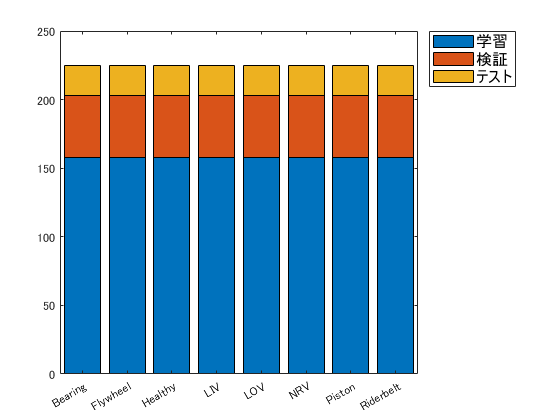

uniqueLabels = unique(ads.Labels);
tblTrain = countEachLabel(adsTrain);
tblValidation = countEachLabel(adsValidation);
tblTest = countEachLabel(adsTest);
H = bar(uniqueLabels,[tblTrain.Count, tblValidation.Count, tblTest.Count],'stacked');
legend(H,{'学習','検証','テスト'},'Location','NorthEastOutside','FontSize',12)

## 可視化

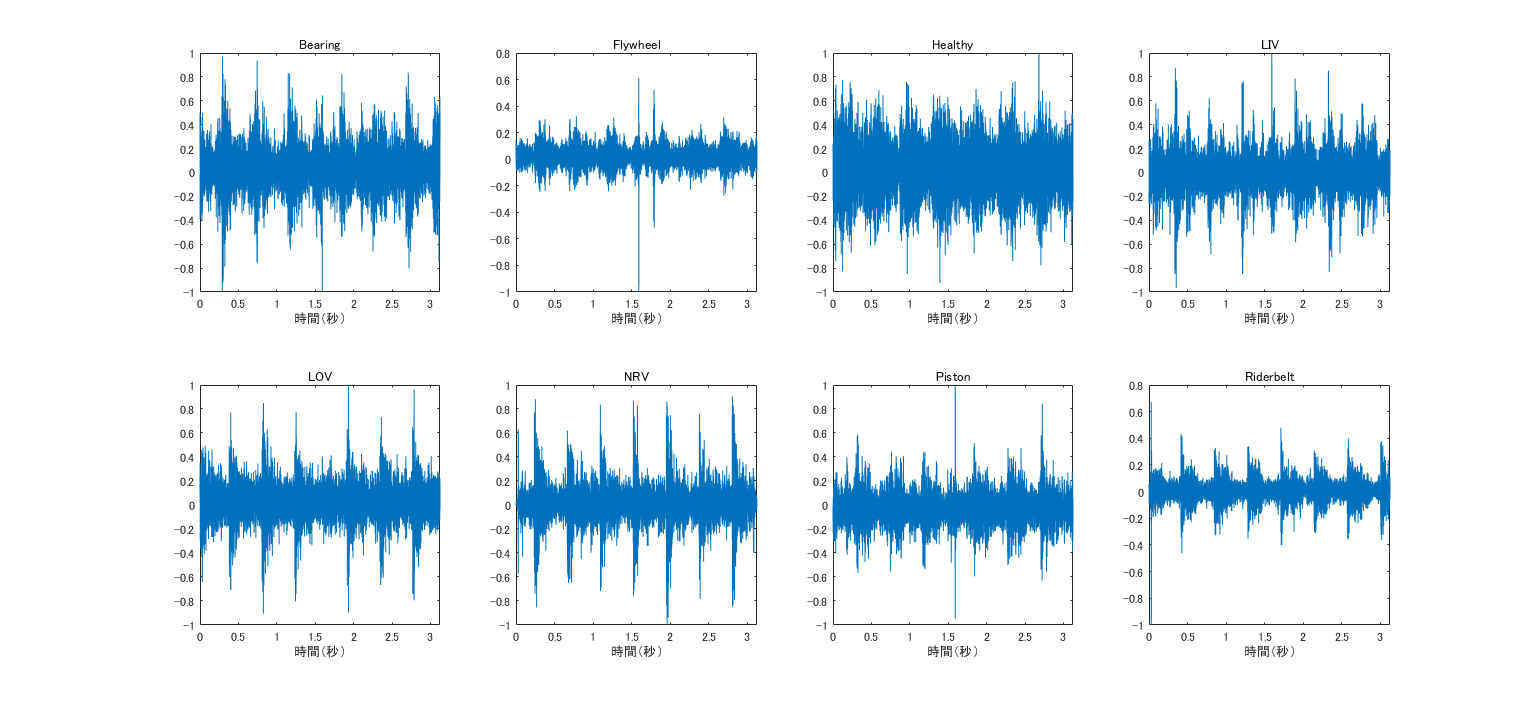

figure('Name','Imported data','Units','Normalized','Position',[0.05, 0.25, 0.80, 0.65]);
for n = 1:numel(uniqueLabels)
    idx = find(adsTrain.Labels==uniqueLabels(n),1);
    [x,fs] = audioread(adsTrain.Files{idx});
    
    t = (0:size(x,1)-1)/fs;
    
    subplot(2,4,n);
    plot(t,x);
    xlabel('時間（秒）')
    title(string(uniqueLabels(n)));
end

## 特徴抽出：

コマンドライン、または、タスクからExtract Audio Featuresを活用

afe = audioFeatureExtractor("SampleRate",fs, ...
    "mfcc",true);

## 学習用

trainFeatures = cell(length(adsTrain.Labels),1);
trainLabels = adsTrain.Labels;
reset(adsTrain);

tic
k = 0;
while hasdata(adsTrain)
    k = k+1;
    [audioIn,~] = read(adsTrain);
    features = extract(afe,audioIn);
    trainFeatures(k) = {features'};
end
toc

経過時間は 8.203083 秒です。


XV = [trainFeatures{:}];
mu = mean(XV,2);
sg = std(XV,[],2);

trainFeaturesSD = trainFeatures;
trainFeaturesSD = cellfun(@(x)(x-mu)./sg,trainFeaturesSD,'UniformOutput',false); %* 標準化

## 検証用

validationFeatures = cell(length(adsValidation.Labels),1);
validationLabels = adsValidation.Labels;
reset(adsValidation);

tic
k = 0;
while hasdata(adsValidation)
    k = k+1;
    [audioIn,~] = read(adsValidation);
    features = extract(afe,audioIn);
    validationFeatures(k) = {features'};
end
toc

経過時間は 2.171766 秒です。



validationFeaturesSD = validationFeatures;
validationFeaturesSD = cellfun(@(x)(x-mu)./sg,validationFeaturesSD,'UniformOutput',false); %* 標準化

## テスト用

testFeatures = cell(length(adsTest.Labels),1);
testLabels = adsTest.Labels;
reset(adsTest);

tic
k = 0;
while hasdata(adsTest)
    k = k+1;
    [audioIn,~] = read(adsTest);
    features = extract(afe,audioIn);
    testFeatures(k) = {features'};
end
toc

経過時間は 1.035712 秒です。



testFeaturesSD = testFeatures;
testFeaturesSD = cellfun(@(x)(x-mu)./sg,testFeaturesSD,'UniformOutput',false); %* 標準化

## ネットワークの構築：LSTM

inputSize = size(trainFeaturesSD{1},1);
numHiddenUnits = 100;
numClasses = numel(unique(trainLabels));

layers = [ ...
    sequenceInputLayer(inputSize)
    bilstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

## 学習のオプション

maxEpochs = 30;
miniBatchSize = 60;
validationFrequency = floor(numel(trainLabels)/miniBatchSize); % 検証頻度

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'InitialLearnRate',0.001,...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest', ...
    'Shuffle','every-epoch', ...
    'Verbose',0, ...
    'ValidationData',{validationFeaturesSD,validationLabels},...
    'ValidationFrequency',validationFrequency,...
    'Plots','training-progress');

## 学習の開始

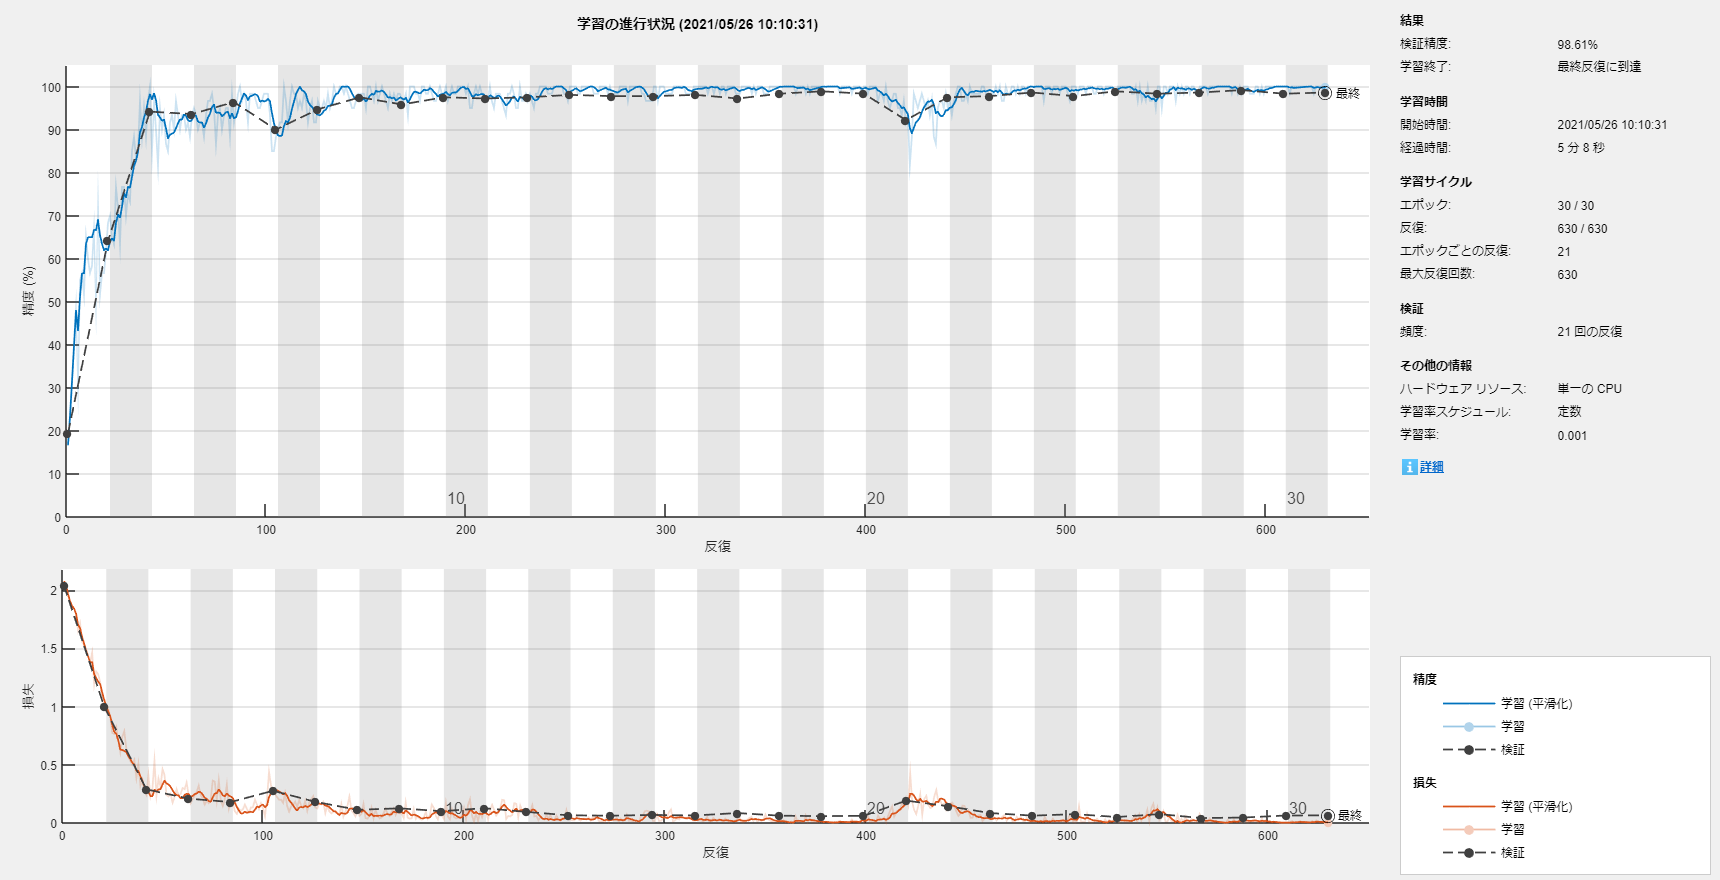

net = trainNetwork(trainFeaturesSD,trainLabels,layers,options);

## 精度検証

predLabels = classify(net,testFeaturesSD, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest');
acc = 100*mean(predLabels == testLabels) %* 精度 (%)

acc = 98.2955

## 混同行列

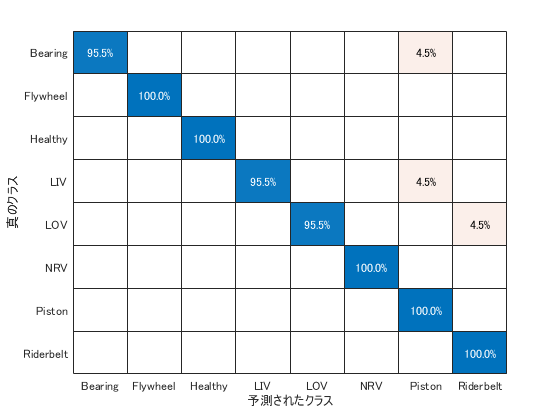

figure; clf;
confusionchart(testLabels, predLabels, "Normalization","row-normalized");

## 精度の可視化

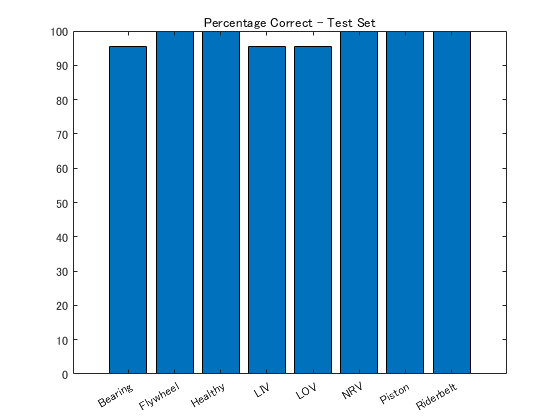

cm = confusionmat(testLabels, predLabels);
genreAccuracy = diag(cm)./tblTest.Count*100;
figure; clf;
bar(genreAccuracy)
set(gca,'XTickLabels',uniqueLabels);
xtickangle(gca,30);
title('Percentage Correct - Test Set');

*Copyright 2021 The MathWorks, Inc.*